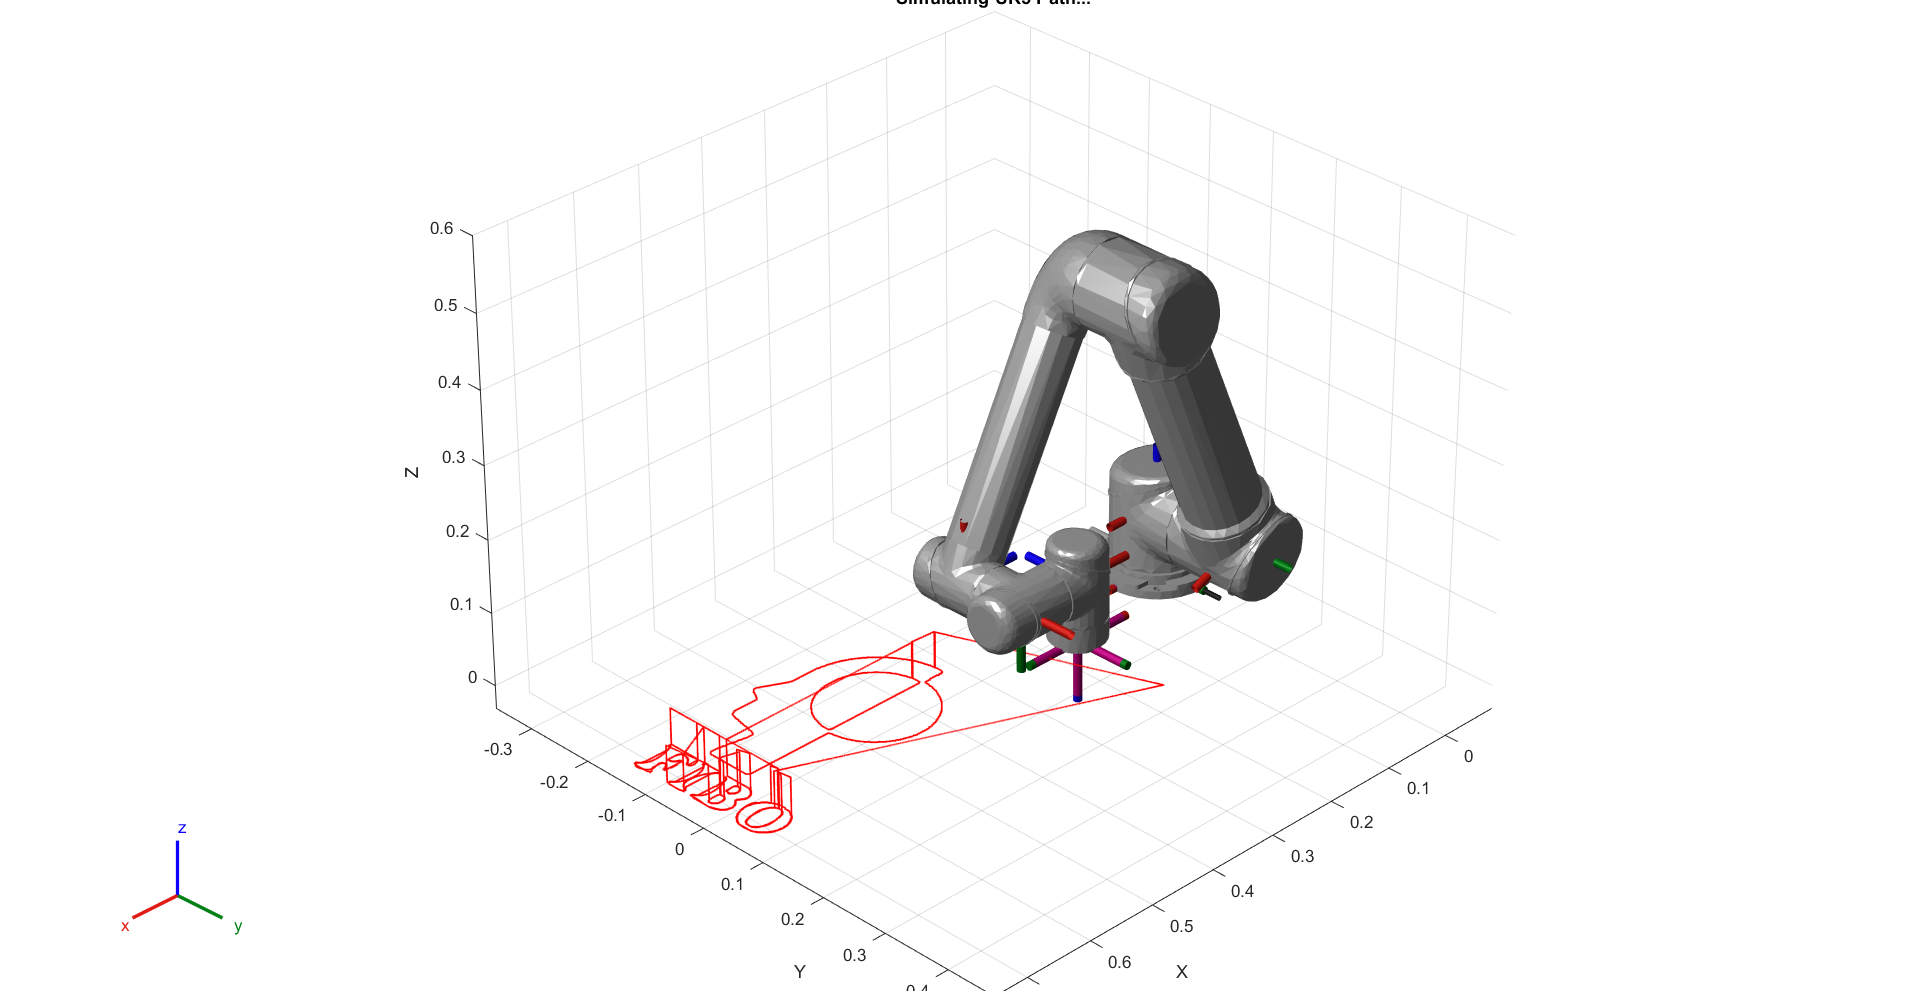

% 1. Load Robot Model & Data
robot = loadrobot('universalUR5', 'DataFormat', 'column');
data = readtable('f_Trajectory.csv');

% Inverse Kinematics Solver
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false; % เพื่อความต่อเนื่อง
weights = [1 1 1 1 1 1]; % ความสำคัญของ [Rx Ry Rz X Y Z]
initialGuess = homeConfiguration(robot); % ท่าเริ่มต้น

figure('Name', 'UR5 Vertical Plotter Simulation', 'Color', 'w');
ax = show(robot, initialGuess);
axis auto; view(135, 30); hold on;
plot3(data.x, data.y, data.z, 'r.', 'MarkerSize', 1); % วาดเส้นทางเป้าหมายรอไว้
title('Simulating UR5 Path...');

% (End Effector Name) ปกติ UR5 คือ 'tool0' หรือ 'ee_link'
eeName = 'tool0'; 

% --- Simulation Loop ---
step = 10; 
dt = data.t(2) - data.t(1);

for i = 1:step:height(data)
    % 1. Target Pose
    targetPos = [data.x(i), data.y(i), data.z(i)];
    
    targetRot = axang2tform([0 1 0 pi]); 
    targetPose = trvec2tform(targetPos) * targetRot(1:4, 1:4); 

    % 2. Solve IK (หา Joint Angles)
    [configSol, solInfo] = ik(eeName, targetPose, weights, initialGuess);
    
    % 3. Update Robot Display
    show(robot, configSol, 'PreservePlot', false, 'FastUpdate', true, 'Parent', ax);
    drawnow;
    
    initialGuess = configSol;
end


fprintf('การจำลองเสร็จสิ้น! หากหุ่นยนต์เคลื่อนที่ตามเส้นสีแดงได้ แสดงว่า Path ใช้ได้ครับ\n');

การจำลองเสร็จสิ้น! หากหุ่นยนต์เคลื่อนที่ตามเส้นสีแดงได้ แสดงว่า Path ใช้ได้ครับ
